# HUMAN KEY POINTS SIM

% @Author: 谢冰
%
% @Description:
%
% @Mail:binxie@stu.xidian.edu.cn
%
clearvars
clc

% cd('E:\3.WorkSpace\Matlab_workspace\Hispark');

cd('E:\onWorking\FamilyGuard\GitOrig\3.algorithm_sim\');


## 标记数据的重标注


% path = 'E:\3.WorkSpace\Matlab_workspace\Hispark\training_dataset\';
path_1 = 'E:\onWorking\FamilyGuard\GitOrig\3.algorithm_sim\dts_sample\singal_person\';
path_2 = 'E:\onWorking\FamilyGuard\GitOrig\3.algorithm_sim\dts_sample\multi_person\';

uf_image_1 = dir('.\dts_sample\singal_person\*.jpg');
uf_label_1 = dir('.\dts_sample\singal_person\*.txt');

uf_image_2 = dir('.\dts_sample\multi_person\*.jpg');
uf_label_2 = dir('.\dts_sample\multi_person\*.txt');



## 测试对象选择


im_tag = uf_image_1(1).name;

dot = strfind(im_tag,'.');
imname = im_tag(1:dot-1)

imname = '00120'

## 单人数据反推——顺序数据

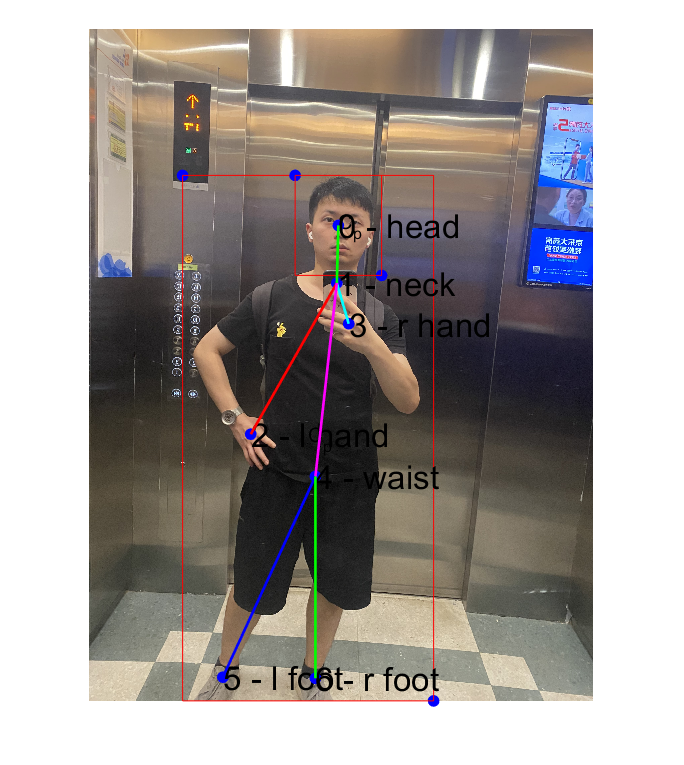

% pic_pth = ['E:\3.WorkSpace\Matlab_workspace\Hispark\training_dataset\',imname,'.jpg'];
% label_pth = ['E:\3.WorkSpace\Matlab_workspace\Hispark\training_dataset\',imname,'.txt'];

pic_pth = [path_1,imname,'.jpg'];
label_pth = [path_1,imname,'.txt'];

Draw_Res_from_Darknet(pic_pth,label_pth);

## 单人数据反推——乱序数据

pic_pth = [path_1,imname,'.jpg'];
label_pth = [path_1,imname,'_disorder','.txt'];

Draw_Res_from_Darknet(pic_pth,label_pth);

## 测试对象重选择


im_tag = uf_image_2(1).name;

dot = strfind(im_tag,'.');
imname = im_tag(1:dot-1)

imname = '00198'

## 多人数据反推——顺序数据

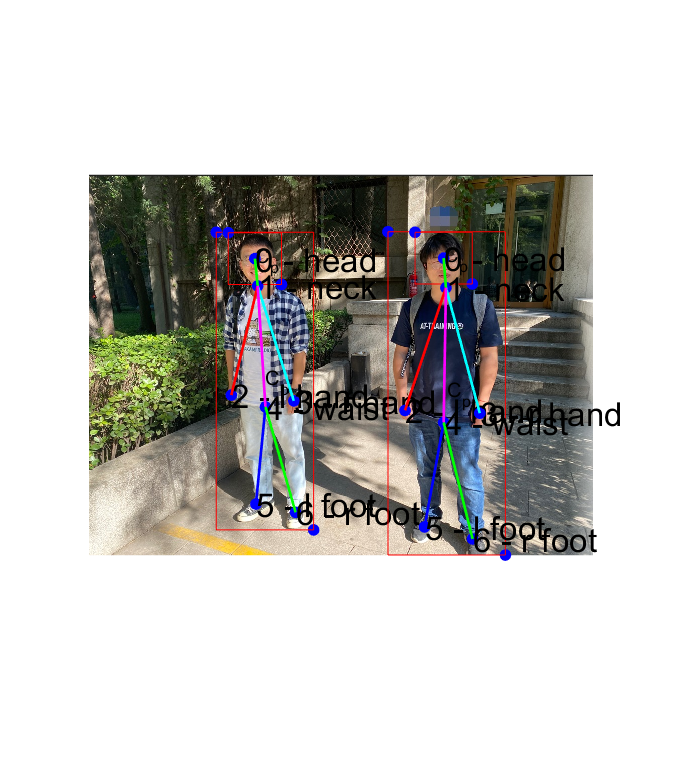


pic_pth = [path_2,imname,'.jpg'];
label_pth = [path_2,imname,'.txt'];

Draw_Res_from_Darknet(pic_pth,label_pth);

## 多人数据反推——乱序数据

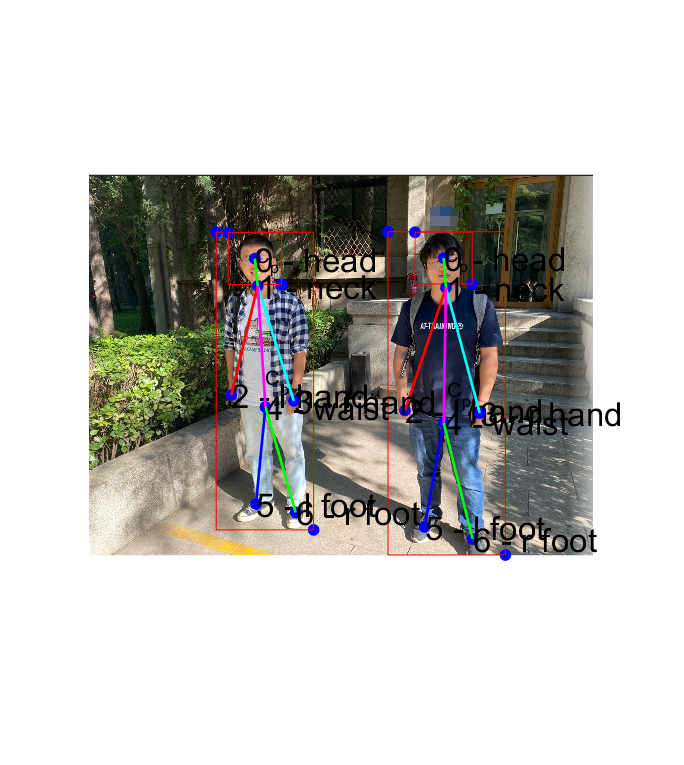

pic_pth = [path_2,imname,'.jpg'];
label_pth = [path_2,imname,'_disorder','.txt'];

Draw_Res_from_Darknet(pic_pth,label_pth);